Code last modified by Yuchen Li, 2024-07-21; Investigate the effects of static magnetic field inhomogeneity, for 16-pulse sequence

clear;clc

J_zhou=1459.5*2*pi; %rad/s, the J value calibrated from experiment

Inhomogeneity_seq=[0,100,1000,3000]*2*pi; %in Hz
% Inhomogeneity_seq=[0,0.1]*2*pi; %in Hz

ave1=1;    %Times of disorder realizations of Jij
ave2=20;    %Times of disorder realizations of inhomogeneity

nqubit=8;

% xi=[0,-0.2,0.2];
xi=[-0.2,0,0.2];

tau=5*1e-6; %average pulse delay, in us

loops=40;

yy=zeros(length(Inhomogeneity_seq),loops);

J=2*J_zhou/nqubit^0.5; %the root of the variance of the normal distribution of J_ij
% Jij_all=normrnd(0,J,[ave,nqubit*(nqubit-1)/2]);%random case

tic
for a=1:ave1

    % Jij=Jij_all(ave1,:); %random case
    Jij=J_zhou*ones(1,nqubit*(nqubit-1)/2); %homogeneous case

    y=zeros(length(Inhomogeneity_seq),loops);

    for b=1:length(Inhomogeneity_seq)

        % h=Inhomogeneity_seq(b)*linspace(-1,1,nqubit); %gradient inhomogeneity  
        h=Inhomogeneity_seq(b)*normrnd(0,1,[1,nqubit]); %random inhomogeneity
        % h=Inhomogeneity_seq(b)*linspace(-1,1,nqubit); %gradient inhomogeneity   

        for c=1:ave2
        y(b,:)=y(b,:)+main(nqubit,Jij,h,xi,tau,loops); 
        end
    end
    yy=yy+y;
end
toc

历时 74.660490 秒。


yy=yy./yy(:,1);

% save('yy_xi_[0,-0.2,0.2].mat','yy')
save('yy_xi_[-0.2,0,0.2].mat','yy')

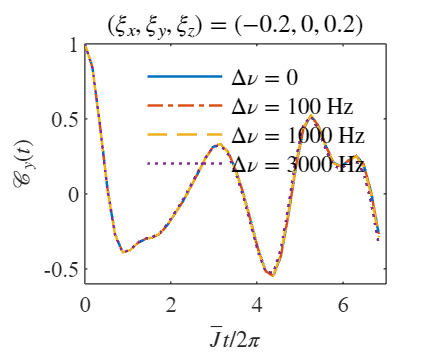

linetype={'-','-.','--',':','-.',':'};

color={  [157 195 231]/255
    [196 151 178]/255
    [243 210 102]/255
[169 184 198]/255
[150 195 125]/255
    };

figure()
x=J_zhou*(24*tau*(0:loops-1))/2/pi;
for i=1:length(Inhomogeneity_seq)
    plot(x,yy(i,:),'LineStyle',linetype{i},'LineWidth',1)
    hold on
end
xlabel('$\bar{J}t/2\pi$','Interpreter','latex')
ylabel('$\mathcal{C}_y(t)$','Interpreter',"latex")
xlim([0,7])
% xticks([0:1:8])
ylim([-0.6 1])
% yticks([-0.2:0.2:1])
fontsize(gcf,9,'points')
fontname(gcf,"Times New Roman")
% set(gca,'YScale','log')
% set(gca,'XScale','log')
% title('$(\xi_x,\xi_y,\xi_z)=(0,-0.2,0.2)$','Interpreter','latex')
title('$(\xi_x,\xi_y,\xi_z)=(-0.2,0,0.2)$','Interpreter','latex')
legend('$\Delta \nu=0$','$\Delta \nu=100$ Hz','$\Delta \nu=1000$ Hz','$\Delta \nu=3000$ Hz','interpreter','latex','box','off','FontSize',9)
set(gcf,'unit','centimeters','position',[10,10,6,5]);

function y=main(nqubit,Jij,h,xi,tau,loops)

[I_single,I_collect]=AngularOperator(nqubit);

Z=I_collect{3};
Y=I_collect{2};
X=I_collect{1};

tau_1=tau*(1+xi(3));
tau_2=tau*(1+xi(2));
tau_3=tau*(1+xi(1));

H_free=Hamiltonian(nqubit,Jij,h,xi);

U_F=pulse(tau_1,tau_2,tau_3);

y=zeros(1,loops);

rho_0=Y;
for loop=1:loops
    U=U_F^(loop-1);
    rho_t=U*rho_0*U';
    y(loop)=real(trace(rho_t*rho_0));
end

### Subfunction [H_D,H_free,H_tar,DipolarOrderState]=Hamiltonian(h,Jij,s,xi_1,xi_2,xi_3)

    function [H_D]=Hamiltonian(nqubit,Jij,h,xi)
        H_D=zeros(2^nqubit);
        index=1;
        for i=1:nqubit
            for j=i+1:nqubit
                H_D=H_D+Jij(index)*(-I_single{1,i}*I_single{1,j}-I_single{2,i}*I_single{2,j}+2*I_single{3,i}*I_single{3,j});
                index=index+1;
            end
            H_D=H_D+h(i)*I_single{3,i};
        end
    end

## Subfunction: U_F=pulse(tau_1,tau_2,tau_3). Evolution operator for single Floquet loop

    function U_F=pulse(tau_1,tau_2,tau_3)
        t1=tau_1;
        t2=tau_2;
        t3=tau_3;
        U_F=U_free(t1)*R(pi/2,X)*U_free(t2)*R(pi/2,Y)*U_free(2*t3)*R(pi/2,Y)*U_free(t2)*R(pi/2,X)*U_free(t1)*...
            U_free(t1)*R(pi/2,X)*U_free(t2)*R(pi/2,Y)*U_free(2*t3)*R(pi/2,Y)*U_free(t2)*R(pi/2,X)*U_free(t1)*...
            U_free(t1)*R(pi/2,-X)*U_free(t2)*R(pi/2,-Y)*U_free(2*t3)*R(pi/2,-Y)*U_free(t2)*R(pi/2,-X)*U_free(t1)*...
            U_free(t1)*R(pi/2,-X)*U_free(t2)*R(pi/2,-Y)*U_free(2*t3)*R(pi/2,-Y)*U_free(t2)*R(pi/2,-X)*U_free(t1);
        function y=U_free(t)
            y=expm(-1i*t*H_free); %不考虑脉冲施加时的系统哈密顿量
        end
    end

#### Subfunction: R(phi, I). Rotation operator

    function y=R(phi,I)
        y=expm(-1i*phi*I); %不考虑脉冲施加时的系统哈密顿量
    end

### Subfunction [I_single,I_collect]=AngularOperator(nqubit). Define angular operators

    function [I_single,I_collect]=AngularOperator(nqubit)

        Ix=1/2*[0,1;1,0];
        Iy=1/2*[0,-1i;1i,0];
        Iz=1/2*[1,0;0,-1];
        I={Ix,Iy,Iz,0.5*eye(2)};

        I_single=cell(3,nqubit); %single-spin operators,
        for n=1:3
            for j=1:nqubit
                Ii0=1;
                for k=1:nqubit
                    if k==j
                        Ii0=kron(Ii0,I{n});
                    else
                        Ii0=kron(Ii0,I{4});
                    end
                end
                I_single{n,j}=sparse(2^(nqubit-1)*Ii0); %n-x,y,z, j-spin number
            end
        end
        %note: I6 is pauli string times 1/2
        I_collect=cell(1,3);%total angular momentum
        for n=1:3
            I_collect{n}=sparse(2^nqubit,2^nqubit);
            for m=1:nqubit
                I_collect{n}=I_single{n,m}+I_collect{n};
            end
        end
    end
end